% script for analyzing twin-grain boundary intersection
%
% chenzhe, 2019-06-13 note.
% Summary on twin variant selection: counts_of_variants vs. SF.
% Variant_size_as_gs_pct vs. Variant/SF

clear;
addChenFunction;

added Chen Functions



% grainDataPath = [uigetdir('D:\WE43_T6_C1_insitu_compression\Analysis_by_Matlab\Grain_1144_data_for_paper_ppt','Folder to save the grain data'),'\'];
dicPath = uigetdir('D:\WE43_T6_C1_insitu_compression\stitched_DIC','pick DIC directory, which contains the stitched DIC data for each stop');
dicFiles = dir([dicPath,'\*.mat']);
dicFiles = struct2cell(dicFiles);
dicFiles = dicFiles(1,:)';

% looks like have to include this part to read the sample name.
[fileSetting,pathSetting] = uigetfile('','select setting file which contains sampleName, stopNames, FOVs, translations, etc');
load_settings([pathSetting,fileSetting],'sampleName','cpEBSD','cpSEM','sampleMaterial','stressTensor');

% load previous data and settings
saveDataPath = [uigetdir('D:\WE43_T6_C1_insitu_compression\Analysis_by_Matlab','choose a path of the saved processed data, or WS, or etc.'),'\'];
saveDataPathInput = saveDataPath;
load([saveDataPath,sampleName,'_traceAnalysis_WS_settings.mat']);
if ~strcmpi(saveDataPath,saveDataPathInput)
    disp('Input saveDataPath is different from that saved in setting.mat file. Check files or code.');
    return;
end

% Load from the pre-labeled results: twinMap, sfMap, struCell.  (cToGbDistMap is omitted, as will no longer be used in this code)
[confirmedLabelFile, confirmedLabelPath] = uigetfile('D:\p\m\DIC_Analysis\','select the results where twin identification was based on trace dir and strain');

[twinGbIntersectionFile, twinGbIntersectionPath] = uigetfile('D:\p\m\DIC_Analysis\20190222_1246_twin_at_boundary_result.mat','select the results for twin-grain boundary intersection');

try
    load([saveDataPath,sampleName,'_EbsdToSemForTraceAnalysis'],'X','Y','boundaryTF','boundaryTFB','ID','gID','gExx','gPhi1','gPhi','gPhi2','gNeighbors','gNNeighbors');
catch
    load([saveDataPath,sampleName,'_EbsdToSemForTraceAnalysis_GbAdjusted'],'X','Y','boundaryTF','boundaryTFB','ID','gID','gExx','gPhi1','gPhi','gPhi2','gNeighbors','gNNeighbors');
end
% modify / or keep an eye on these settings for the specific sample to analyze  ------------------------------------------------------------------------------------
STOP = {'0','1','2','3','4','5','6','7'};
B=1;    % 0-based B=1.  1-based B=0.
iE_start = 2;   % elongation levels to analyze. 0-based.
iE_stop = 5;

% file name prefixes
f1 = 'WE43_T6_C1_s';
f2 = '_';

debugTF = 0;

## [data] strain data. Convert into v7.3 for partial loading

clear strainFile;
for iE = iE_start-1:iE_stop
    strainFileName = [dicPath,'\',f2,STOP{iE+B}];
    disp(strainFileName);
    if ~exist([strainFileName,'_v73.mat'],'file')
        load(strainFileName);
        clear('exy_corrected');
        load(strainFileName,'exy_corrected');   % if 'exy_corrected' does not exist, this does not give error, rather, just warning.
        
        if exist('exy_corrected','var')&&(1==exy_corrected)
            disp('================= exy already corrected ! ========================');
            exy_corrected = 1;
        else
            disp('================= exy being corrected here ! =======================');
            exy = -exy;
            exy_corrected = 1;
        end
        % remove bad data points
        exx(sigma==-1) = nan;
        exy(sigma==-1) = nan;
        eyy(sigma==-1) = nan;
        qt_exx = quantile(exx(:),[0.0013,0.9987]); qt_exx(1)=min(-1,qt_exx(1)); qt_exx(2)=max(1,qt_exx(2));
        qt_exy = quantile(exy(:),[0.0013,0.9987]); qt_exy(1)=min(-1,qt_exy(1)); qt_exy(2)=max(1,qt_exy(2));
        qt_eyy = quantile(eyy(:),[0.0013,0.9987]); qt_eyy(1)=min(-1,qt_eyy(1)); qt_eyy(2)=max(1,qt_eyy(2));
        ind_outlier = (exx<qt_exx(1))|(exx>qt_exx(2))|(exy<qt_exy(1))|(exy>qt_exy(2))|(eyy<qt_eyy(1))|(eyy>qt_eyy(2));
        exx(ind_outlier) = nan;
        exy(ind_outlier) = nan;
        eyy(ind_outlier) = nan;
        
        outlier_removed = 1;
        save([strainFileName,'_v73.mat'],'outlier_removed','exy_corrected','-v7.3');
        
        myFile = matfile(strainFileName);
        myFields = who(myFile);
        for ii=1:length(myFields)
            save([strainFileName,'_v73.mat'],myFields{ii},'-append','-v7.3');
        end
    else
        disp('v7.3 file already exist');
    end
    strainFile{iE} = matfile([strainFileName,'_v73.mat']);
end

D:\WE43_T6_C1_insitu_compression\stitched_DIC\_1


v7.3 file already exist


D:\WE43_T6_C1_insitu_compression\stitched_DIC\_2


v7.3 file already exist


D:\WE43_T6_C1_insitu_compression\stitched_DIC\_3


v7.3 file already exist


D:\WE43_T6_C1_insitu_compression\stitched_DIC\_4


v7.3 file already exist


D:\WE43_T6_C1_insitu_compression\stitched_DIC\_5


v7.3 file already exist


## (0) load data, using SF threshold values to assign active twin system, and make maps

Load cluster number maps (cleaned).

clusterNumberMapCell = cell(1,length(STOP)-1);
for iE = []%iE_start:iE_stop
    fName_c2t_result = [sampleName,'_s',num2str(STOP{iE+B}),'_cluster_to_twin_result.mat'];
    load([saveDataPath,fName_c2t_result],'clusterNumMapCleaned');
    clusterNumberMapCell{iE} = clusterNumMapCleaned;
end

% Load from the pre-labeled results: twinMapCell, sfMapCell, struCell.  (cToGbDistMapCell is omitted, as will no longer be used in this code)
% load(fullfile(confirmedLabelPath,confirmedLabelFile),'struCell','twinMapCell','trueTwinMapCell','sfMapCell','tNote');
load(fullfile(confirmedLabelPath,confirmedLabelFile),'trueTwinMapCell');

## load previous twin_gb interaction result

load(fullfile(twinGbIntersectionPath, twinGbIntersectionFile));
% Make unique grain boundary map, and a list of the unique grain boundaries
[~, boundaryID, neighborID, ~, ~] = find_one_boundary_from_ID_matrix(ID);

found one-pixel width boundaryTF and tripleTF


uniqueBoundary = max(boundaryID,neighborID)*10000 + min(boundaryID,neighborID);
uniqueBoundaryList = unique(uniqueBoundary(:)); 
uniqueBoundaryList(uniqueBoundaryList==0) = [];
clear boundaryID neighborID;

## (4) Study twin variant selection

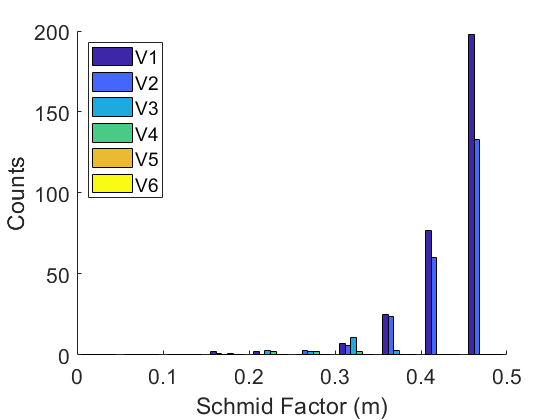

close all;
SF_th = 0.35;   % threshold for SF and SF_normalized to consider as outliers
SF_n_th = 0.85;
% first, find out new active twin system at each level
T = cell2table(cell(0,8));
T.Properties.VariableNames = {'iE','ID','ts','variant','SF','SF_normalized','v1_active_TF','vPct'};
for iE = 2:5    
    for iS = 1:length(struCell{iE})
        % find out new activeTS
        activeTS = logical(sum(struCell{iE}(iS).cTrueTwin,1));
        if iE==iE_start
            activeTS_pre = [0 0 0 0 0 0];
        else
            activeTS_pre = logical(sum(struCell{iE-1}(iS).cTrueTwin,1));
        end
        newActiveTS = (activeTS - activeTS_pre)>0;
        SF_nor = struCell{iE}(iS).tSF./max(struCell{iE}(iS).tSF);
        [~,SF_order]=ismember(SF_nor,sort(SF_nor,'descend'));   % find index of ranking of element in array
        
        % ii is the twin system index
        for ii=1:length(newActiveTS)
           if newActiveTS(ii)>0
               [~,idx] = max(struCell{iE}(iS).tSF);
               T = [T; {iE, struCell{iE}(iS).gID, struCell{iE}(iS).tLabel(ii), SF_order(ii), struCell{iE}(iS).tSF(ii), SF_nor(ii), activeTS(idx)>0, struCell{iE}(iS).tVol(ii)/struCell{iE}(iS).gVol}];
           end
        end              
        
    end
end

% (1) bar plot variant
Ng = [];
figure; hold on;
set(gca,'ColorOrder',parula(6));
edges_SF = 0:0.05:0.5;
for ig = 1:6
   ind = T.variant==ig;
   t = T(ind,:);
   Ng(:,ig) = histcounts(t.SF,edges_SF);
end
bar(edges_SF(1:end-1)+0.025,Ng, 1);
legend('V1','V2','V3','V4','V5','V6','Location','northwest');
set(gca,'fontsize',16,'xlim',[0 0.5]);
xlabel('Schmid Factor (m)');
ylabel('Counts');

% title(['iE=',num2str(iE)],'fontweight','normal');


% count number of variant
N = histcounts(T.variant,[0.5:6.5]);
table(N(1),N(2),N(3),N(4),N(5),N(6),'VariableNames',{'v1','v2','v3','v4','v5','v6'})

ans = 1×6 table
    v1     v2     v3    v4    v5    v6
    ___    ___    __    __    __    __
    311    227    19    7     0     0 



% (2) plot SF vs normalized_SF
figure; hold on;
set(gca,'ColorOrder',parula(6))
for ig = 1:6
   ind = T.variant==ig;
   t = T(ind,:);
   plot(t.SF, t.SF_normalized,'.','markersize',18);
end
xlabel('Schmid Factor');
ylabel('Schmid Factor normalized');
set(gca,'fontsize',18,'xlim',[0.1 0.5],'ylim',[0.4 1]);
legend({'V1','V2','V3','V4','V5','V6'},'Location','southeast');

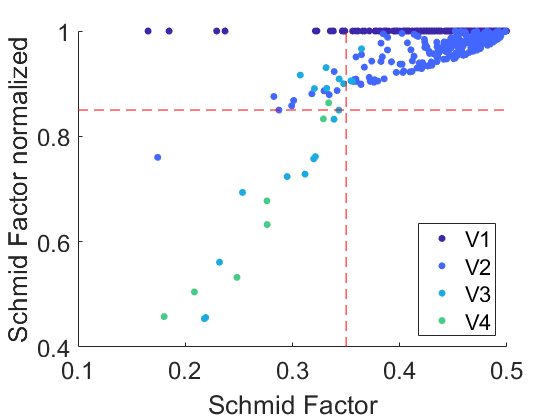

line(get(gca,'xlim'),[SF_n_th, SF_n_th],'color','r','LineStyle','--','HandleVisibility','off');
line([SF_th, SF_th], get(gca,'ylim'),'color','r','LineStyle','--','HandleVisibility','off');

## (4.2) find out intereting grains to look at

close all; clc;
% m = [gID, ts, variant, SF, SF_normalized, is_highest_v_active]
iE = iE

iE = 5

SF_th = SF_th

SF_th = 0.3500

SF_n_th = SF_n_th

SF_n_th = 0.8500

ind = (T.SF < SF_th)&(T.SF_normalized < SF_n_th);
t = T(ind,:);

disp(['# of grains of interest = ',num2str(length(t.ID))]);

# of grains of interest = 18


iE=2 , gID=195, TS=21


Predicted strain components:


   -0.0432    0.0210    0.0220


Measured cluster centroid


   -0.0174   -0.0019    0.0165


Current plot held


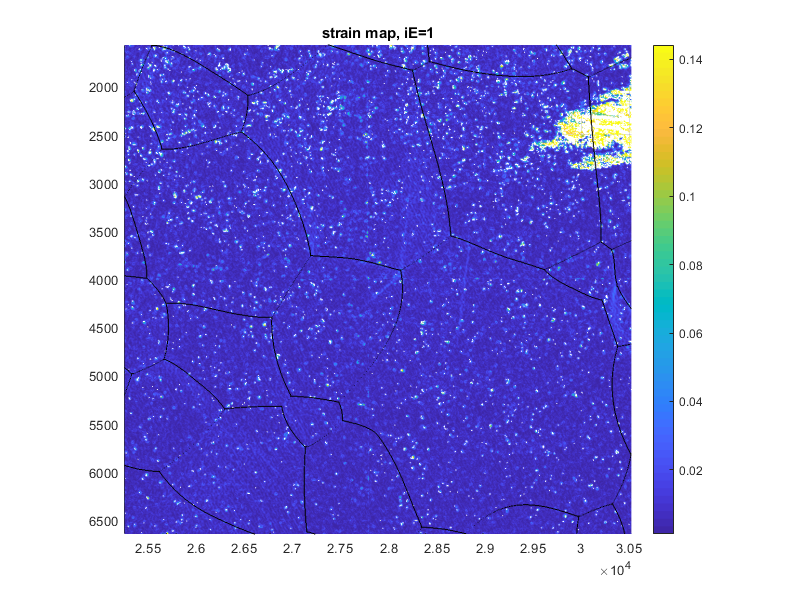

Current plot held


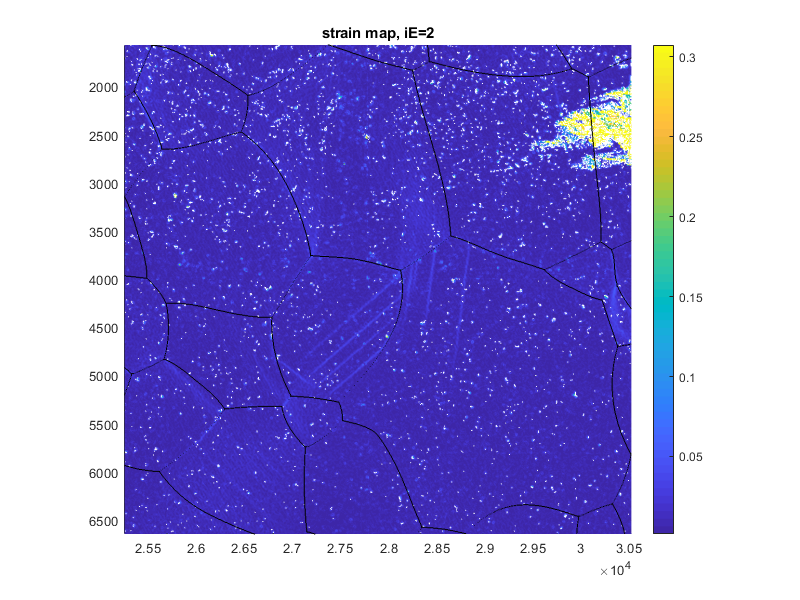

Current plot held


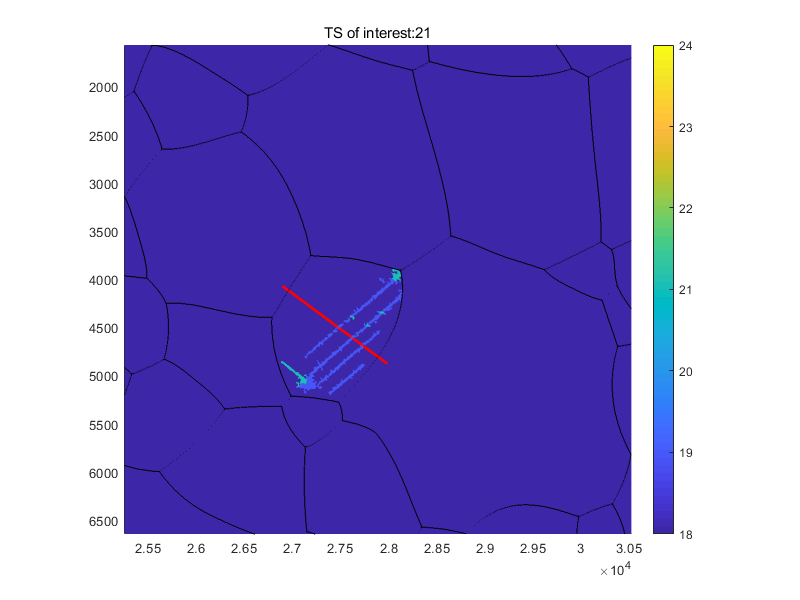

Current plot held


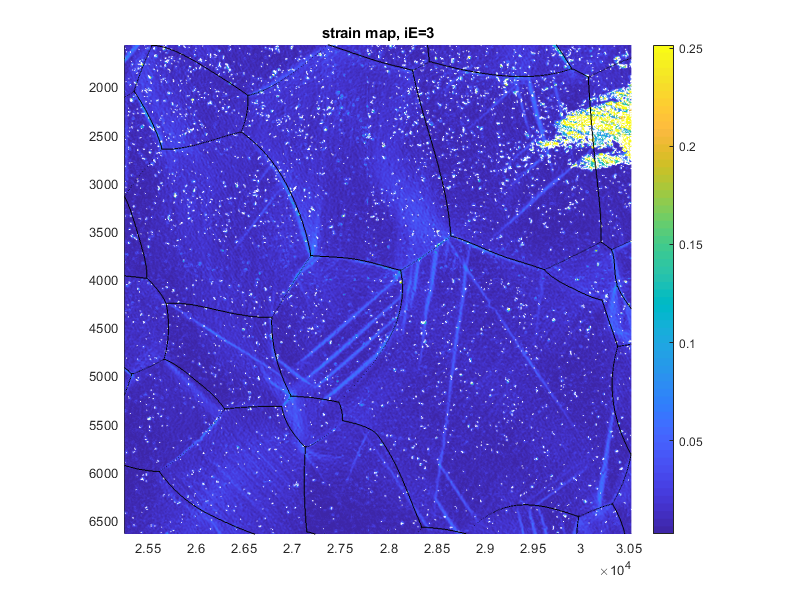

Current plot held


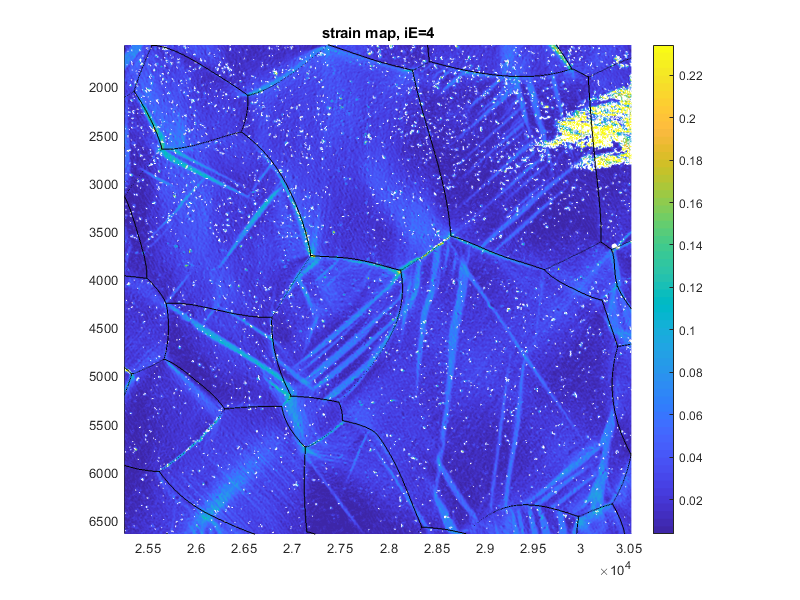

Current plot held


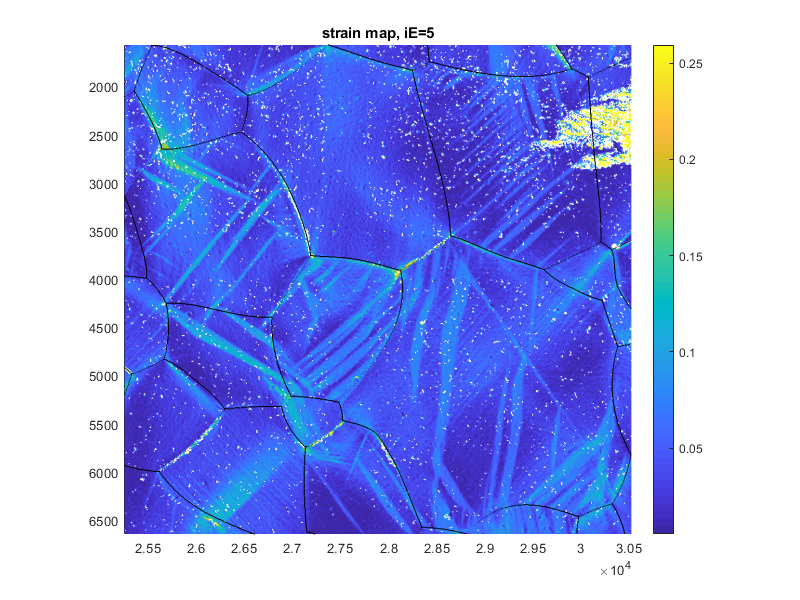

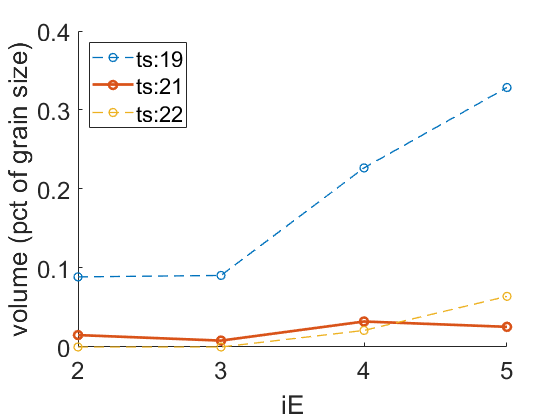

for ii = 1
    iE = t.iE(ii);
    ID_current = t.ID(ii);
    ts_current = t.ts(ii);
    iS = find(arrayfun(@(x) x.gID == ID_current, struCell{iE}));
    % (A) Find the active ts (label, index), and display the predicted twin strain
    it = find(struCell{iE}(iS).tLabel==ts_current);
    disp(['iE=',num2str(iE),' , gID=',num2str(ID_current),', TS=',num2str(ts_current)]);
    disp('Predicted strain components:');
    disp(struCell{iE}(iS).tStrain(it,:));
    % (B) calculate theoretical trace direction.
    ind_euler = find(gID==ID_current);
    euler = [gPhi1(ind_euler),gPhi(ind_euler),gPhi2(ind_euler)];
    if (1==eulerAligned)
        % g = euler_to_transformation(euler,[0,0,0],[0,0,0]);
        [abs_schmid_factor, ~, burgersXY] = trace_analysis_TiMgAl(euler, [0,0,0], [0,0,0], stressTensor, sampleMaterial, 'twin');
    else
        % g = euler_to_transformation(euler,[-90,180,0],[0,0,0]); % setting-2
        [abs_schmid_factor, ~, burgersXY] = trace_analysis_TiMgAl(euler, [-90,180,0], [0,0,0], stressTensor, sampleMaterial, 'twin'); % setting-2
    end
    [ssa, c_a, nss, ntwin, ssGroup] = define_SS(sampleMaterial,'twin');
    traceDir = abs_schmid_factor(nss+1:nss+ntwin,3);
    mult_factor = ones(size(traceDir));
    mult_factor(traceDir<0) = 1;
    mult_factor(traceDir>=0) = -1;
    traceND = traceDir + 90*mult_factor;    % convert traceDir to traceND
    % (C) find out which cluster correspond to it, and display the cluster strain 
    iCs = find(struCell{iE}(iS).cTrueTwin(:,it)==1);
    % (D) check measured cluster strain
    disp('Measured cluster centroid');
    disp(struCell{iE}(iS).cCen(iCs,:));
    
    % (E) plot local maps
    ID_neighbor = gNeighbors((gID==ID_current),1:gNNeighbors(gID==ID_current));
    
    ind_local = ismember(ID, [ID_current,ID_neighbor]); %ismember(ID, [ID_current,ID_neighbor]);
    
    % Make it one data point wider on each side
    indC_min = max(1, find(sum(ind_local, 1), 1, 'first')-1);
    indC_max = min(size(ID,2), find(sum(ind_local, 1), 1, 'last')+1);
    indR_min = max(1, find(sum(ind_local, 2), 1, 'first')-1);
    indR_max = min(size(ID,1), find(sum(ind_local, 2), 1, 'last')+1);
    
    ID_local = ID(indR_min:indR_max, indC_min:indC_max);
    x_local = X(indR_min:indR_max, indC_min:indC_max);
    y_local = Y(indR_min:indR_max, indC_min:indC_max);
    boundaryTF_local = boundaryTF(indR_min:indR_max, indC_min:indC_max);
    
    for ie = iE-1 : iE_stop
        eMap_local = calculate_effective_strain(strainFile{ie}.exx(indR_min:indR_max, indC_min:indC_max), strainFile{ie}.exy(indR_min:indR_max, indC_min:indC_max), strainFile{ie}.eyy(indR_min:indR_max, indC_min:indC_max));
        myplot(x_local, y_local, eMap_local, boundaryTF_local);
        % eMap_local = strainFile{ie}.exx(indR_min:indR_max, indC_min:indC_max);
        % myplot(x_local, y_local, strainFile{ie}.exx(indR_min:indR_max, indC_min:indC_max), boundaryTF_local);
        % myplot(x_local, y_local, strainFile{ie}.exy(indR_min:indR_max, indC_min:indC_max), boundaryTF_local);
        % myplot(x_local, y_local, strainFile{ie}.eyy(indR_min:indR_max, indC_min:indC_max), boundaryTF_local);
        title(['strain map, iE=',num2str(ie)]);
        if ie==iE
            trueTwinMapLocal = trueTwinMapCell{ie}(indR_min:indR_max, indC_min:indC_max);
            myplot(x_local, y_local, trueTwinMapLocal, boundaryTF_local); caxis([18,24]);
            title(['TS of interest:',num2str(t.ts(ii))],'fontweight','normal');
            % (F) plot a red line indicating the trace of interest
            px = mean(x_local(ID_local==ID_current));
            py = mean(y_local(ID_local==ID_current));
            r = 0.5 * mean(range(x_local(ID_local==ID_current)),range(y_local(ID_local==ID_current)));
            a = traceDir(it);
            line([px-r*cosd(a), px+r*cosd(a)], [py-r*sind(a), py+r*sind(a)],'color','r','linewidth',2);
        end
    end
    
    % (E) find out twin volume and plot
    tVol = [];
    for ie = iE_start:iE_stop
        tVol = [tVol; struCell{ie}(iS).tVol];
    end
    figure; hold on;
    % set(gca,'ColorOrder',parula(6));
    legend_string = {};
    gVol =struCell{iE}(iS).gVol;
    for jj = 1:6
        if any(tVol(:,jj))
            if jj==it
                plot(iE_start:iE_stop, tVol(:,jj)./gVol,'-o','LineWidth',2);
            else
                plot(iE_start:iE_stop, tVol(:,jj)./gVol,'--o','LineWidth',1);
            end
            legend_string = {legend_string{:},['ts:',num2str(jj+nss)]};
        end
    end
    legend(legend_string,'Location','northwest');
    set(gca,'fontsize',18);
    xlabel('iE');
    ylabel('volume (pct of grain size)');



end

## Then, study the volume fraction (or evolution), group by (1) variant, (2) SF, (3) SF_normalized

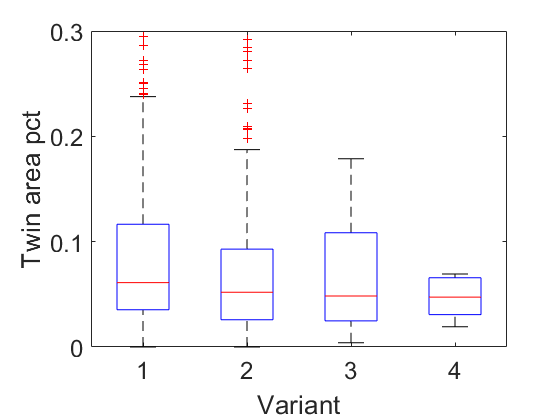

close all;
% (1) group by variant
gv = T.variant;
figure;
boxplot(T.vPct, gv);
set(gca,'fontsize',18,'ylim',[0 0.3]);
xlabel('Variant');
ylabel('Twin area pct');

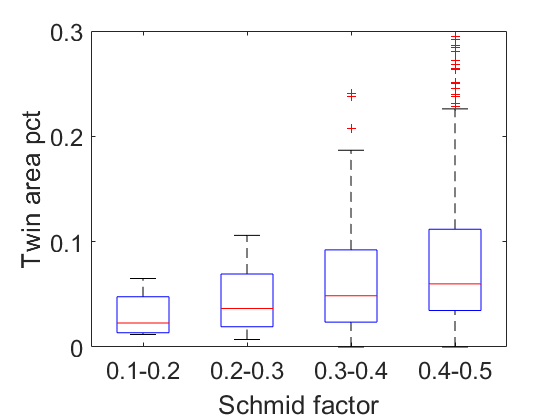


% (2) group by SF
gv = floor((T.SF-0)/0.1);
figure;
boxplot(T.vPct, gv);
xlabel('Schmid factor');
ylabel('Twin area pct');
set(gca,'fontsize',18,'XTickLabel',{'0.1-0.2', '0.2-0.3','0.3-0.4','0.4-0.5'},'ylim',[0 0.3]);

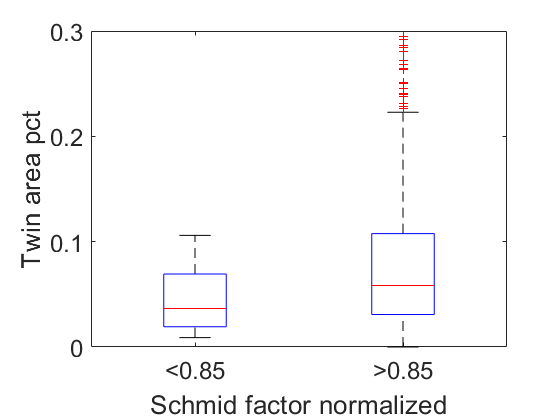


% (3) group by SF_normalized
gv = (T.SF_normalized>0.85);
figure;
boxplot(T.vPct, gv);
xlabel('Schmid factor normalized');
ylabel('Twin area pct');
set(gca,'fontsize',18,'XTickLabel',{'<0.85','>0.85'},'ylim',[0 0.3]);